**LEP 6-1 : Gas phase reaction in a Microreactor- Molar flow rates**

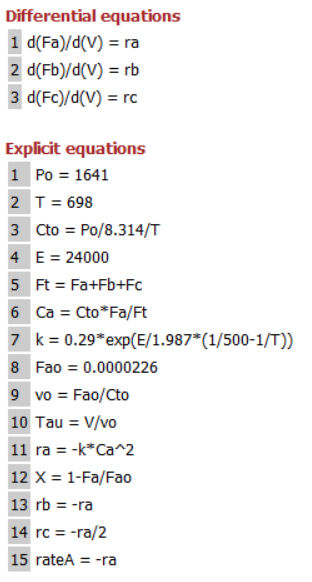

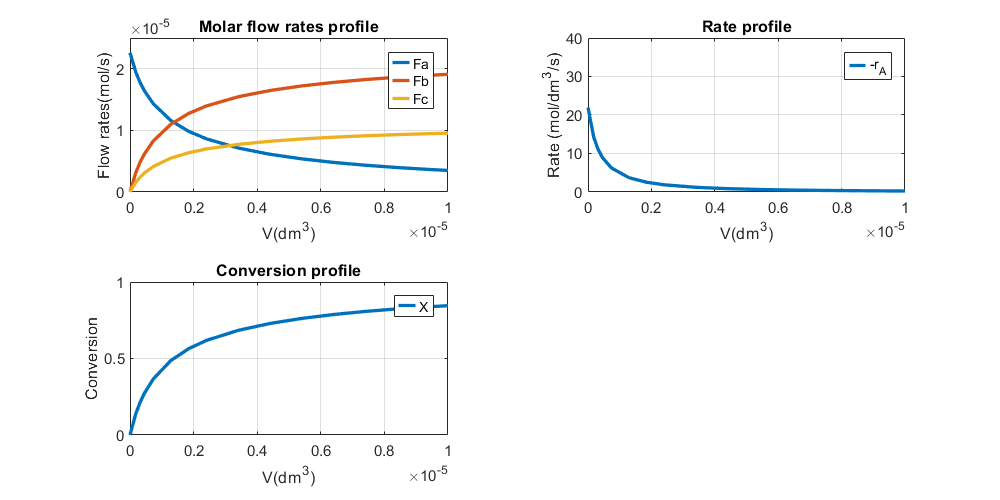

Vspan = [0 1.0E-05];
y0 = [2.26E-05; 0; 0]; 
T = 698; 
P0=1641;
E =24000; 
[v y]=ode113(@(v,y)ODEfun(v,y,T,P0,E),Vspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,800,400])
Fa=y(:,1);
Fb=y(:,2);
Fc=y(:,3);
nexttile
plot(v,Fa,v,Fb,v,Fc,'LineWidth',2)
leg=legend('Fa','Fb','Fc');
xlabel('V(dm^3)')
ylabel('Flow rates(mol/s)')
axis([0 1e-05 0 25e-06])
title('Molar flow rates profile')
leg.ItemTokenSize=[10,10];
grid on
z=size(y);
Cto = P0 / 8.314 / T;
Fao = 0.0000226;
k = 0.29 * exp(E / 1.987 * (1 / 500 - (1 / T)));
for i=1 : z(1,1)
Ft(i) = Fa(i) + Fb(i) + Fc(i); 
Ca(i) = Cto * Fa(i) / Ft(i); 
ra(i) = 0 - (k * Ca(i) ^ 2); 
X(i) = 1 - (Fa(i) / Fao); 
rb(i) = 0 - ra(i); 
end
nexttile
plot(v,-ra(1:z(1,1)),'LineWidth',2)
xlabel('V(dm^3)')
ylabel('Rate (mol/dm^3/s)')
axis([0 1e-05 0 40])
leg=legend('-r_A');
leg.ItemTokenSize=[10,10];
title('Rate profile')
grid on
nexttile
plot(v,X(1:z(1,1)),'LineWidth',2)
xlabel('V(dm^3)')
ylabel('Conversion')
axis([0 1e-05 0 1])
leg=legend('X');
leg.ItemTokenSize=[10,10];
title('Conversion profile')
grid on

function dYfuncvecdV = ODEfun(V,Yfuncvec,T,P0,E); 
Fa = Yfuncvec(1); 
Fb = Yfuncvec(2); 
Fc = Yfuncvec(3); 
% Explicit equations
Cto = P0 / 8.314 / T; 
Ft = Fa + Fb + Fc; 
Ca = Cto * Fa / Ft; 
k = 0.29 * exp(E / 1.987 * (1 / 500 - (1 / T))); 
Fao = 0.0000226; 
vo = Fao / Cto; 
ra = 0 - (k * Ca ^ 2); 
X = 1 - (Fa / Fao); 
rb = 0 - ra; 
rc = 0 - (ra / 2); 
% Differential equations
dFadV = ra; 
dFbdV = rb; 
dFcdV = rc; 
dYfuncvecdV = [dFadV; dFbdV; dFcdV]; 
end